# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                  displayData.m      ex3.mlx            ex3_companion.mlx  ex3weights.mat     lib                oneVsAll.m         predictOneVsAll.m  submit.m           
..                 ex2.pdf            ex3_companion.mat  ex3data1.mat       fmincg.m           lrCostFunction.m   predict.m          sigmoid.m          token.mat          



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/)

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

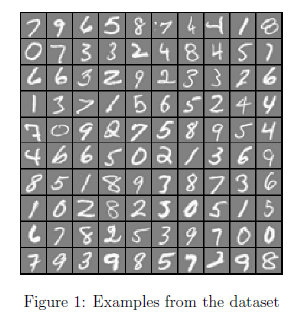                        

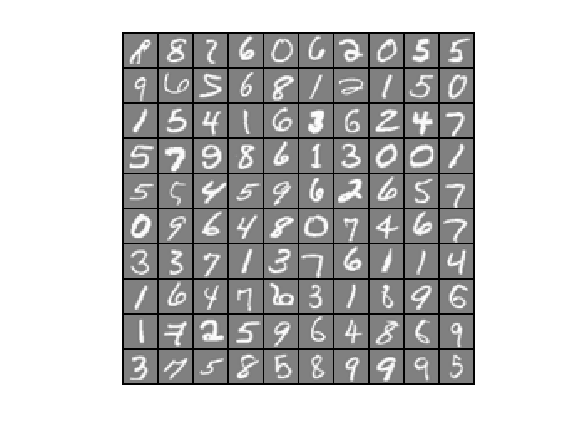

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \;=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \;-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \;-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \;-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\;\theta^T \left(x^{\left(1\right)} \right)-\\
-{\;\theta }^T \left(x^{\left(2\right)} \right)\;-\\
\vdots \\
-{\;\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \;$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \;} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \;} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \;} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \;} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_i \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \; & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \; & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

theta =      0
    -1
     1
     2



fprintf('Cost: %f | Expected cost: 2.534819\n',J);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('Gradients:\n'); fprintf('%f\n',grad);

Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

   0   0   1   0   0   0   0   0   0   0



Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta =          0
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 2.802128e-01


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0001


Iteration     2 | Cost: 9.454389e-02


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0001
    0.0001
   -0.0001


Iteration     3 | Cost: 5.704641e-02


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
    0.0001
    0.0008
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0000
    0.0003
   -0.0001


Iteration     4 | Cost: 4.688190e-02


theta =          0
         0
         0
    0.0000
   -0.0000
   -0.0001
   -0.0002
    0.0005
    0.0018
   -0.0002


Iteration     5 | Cost: 3.759021e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0003
    0.0009
    0.0031
   -0.0002


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0006
    0.0021
   -0.0002


Iteration     6 | Cost: 3.522008e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0003
    0.0006
    0.0027
   -0.0002


Iteration     7 | Cost: 3.234531e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0002
    0.0029
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0005
    0.0027
   -0.0002


Iteration     8 | Cost: 3.145034e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0028
   -0.0001


Iteration     9 | Cost: 3.008919e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0027
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0028
   -0.0001


Iteration    10 | Cost: 2.994639e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0003
    0.0027
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
    0.0002
    0.0027
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0000
    0.0027
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0005
    0.0026
   -0.0001


Iteration    11 | Cost: 2.678528e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0000
   -0.0019
    0.0022
   -0.0000


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0006
    0.0025
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0006
    0.0025
   -0.0001


Iteration    12 | Cost: 2.660323e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0007
    0.0025
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0009
    0.0025
   -0.0001


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0014
    0.0023
   -0.0000


Iteration    13 | Cost: 2.493301e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0002
    0.0000
   -0.0028
    0.0020
    0.0000


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0016
    0.0023
   -0.0000


Iteration    14 | Cost: 2.475211e-02


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0000
   -0.0018
    0.0022
   -0.0000


theta =          0
         0
         0
    0.0000
   -0.0001
   -0.0001
   -0.0000
   -0.0021
    0.0022
   -0.0000


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0032
    0.0019
    0.0000


Iteration    15 | Cost: 2.318421e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0049
    0.0016
    0.0001


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0035
    0.0019
    0.0001


Iteration    16 | Cost: 2.287050e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0001
   -0.0039
    0.0018
    0.0001


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0017
    0.0001


Iteration    17 | Cost: 2.160258e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0044
    0.0018
    0.0001


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    18 | Cost: 2.120371e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0044
    0.0018
    0.0001


Iteration    19 | Cost: 2.064125e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0018
    0.0001


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    20 | Cost: 2.055695e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    21 | Cost: 2.045466e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0045
    0.0018
    0.0001


Iteration    22 | Cost: 2.029177e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0018
    0.0001


Iteration    23 | Cost: 2.005296e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0019
    0.0001


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0018
    0.0001


Iteration    24 | Cost: 1.995949e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0046
    0.0019
    0.0001


Iteration    25 | Cost: 1.982849e-02


theta =          0
         0
         0
    0.0000
   -0.0002
   -0.0002
    0.0002
   -0.0047
    0.0019
    0.0001


Iteration    26 | Cost: 1.975129e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0002
   -0.0003
    0.0002
   -0.0048
    0.0019
    0.0001


theta = 401×1
         0
         0
         0
    0.0000
   -0.0002
   -0.0003
    0.0002
   -0.0050
    0.0019
    0.0001


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0003
    0.0003
   -0.0055
    0.0019
    0.0001


Iteration    27 | Cost: 1.897815e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0004
   -0.0070
    0.0020
    0.0001


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0003
    0.0003
   -0.0057
    0.0019
    0.0001


Iteration    28 | Cost: 1.887065e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0061
    0.0019
    0.0001


Iteration    29 | Cost: 1.869107e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0060
    0.0019
    0.0001


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0061
    0.0019
    0.0001


Iteration    30 | Cost: 1.863223e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0003
   -0.0061
    0.0019
    0.0001


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0003
    0.0003
   -0.0061
    0.0019
    0.0001


Iteration    31 | Cost: 1.837393e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0064
    0.0018
    0.0001


Iteration    32 | Cost: 1.816950e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0066
    0.0017
    0.0001


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0069
    0.0016
    0.0002


Iteration    33 | Cost: 1.781689e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0006
   -0.0084
    0.0010
    0.0002


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0071
    0.0015
    0.0002


Iteration    34 | Cost: 1.774664e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0071
    0.0015
    0.0002


Iteration    35 | Cost: 1.767442e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0071
    0.0015
    0.0002


Iteration    36 | Cost: 1.758469e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0005
   -0.0073
    0.0015
    0.0002


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0072
    0.0015
    0.0002


Iteration    37 | Cost: 1.756884e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0072
    0.0015
    0.0002


theta = 401×1
         0
         0
         0
    0.0000
   -0.0003
   -0.0004
    0.0004
   -0.0072
    0.0015
    0.0002


Iteration    38 | Cost: 1.753421e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0005
   -0.0073
    0.0015
    0.0002


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0005
   -0.0075
    0.0014
    0.0002


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0004
    0.0005
   -0.0079
    0.0013
    0.0002


Iteration    39 | Cost: 1.728288e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0005
    0.0006
   -0.0087
    0.0012
    0.0002


Iteration    40 | Cost: 1.702069e-02


theta = 401×1
         0
         0
         0
    0.0000
   -0.0004
   -0.0005
    0.0007
   -0.0094
    0.0010
    0.0003


theta = 401×1
         0
         0
         0
    0.0001
   -0.0005
   -0.0006
    0.0008
   -0.0109
    0.0006
    0.0003


Iteration    41 | Cost: 1.621409e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0006
   -0.0007
    0.0010
   -0.0129
    0.0001
    0.0004


Iteration    42 | Cost: 1.554077e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0007
   -0.0008
    0.0012
   -0.0153
   -0.0005
    0.0005


Iteration    43 | Cost: 1.505604e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0009
   -0.0010
    0.0016
   -0.0196
   -0.0015
    0.0006


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0173
   -0.0009
    0.0006


Iteration    44 | Cost: 1.473567e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0173
   -0.0009
    0.0006


Iteration    45 | Cost: 1.449424e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0010
    0.0006


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0009
    0.0006


Iteration    46 | Cost: 1.435487e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0010
    0.0006


Iteration    47 | Cost: 1.425449e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0010
    0.0006


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0010
    0.0006


Iteration    48 | Cost: 1.420412e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0010
    0.0006


Iteration    49 | Cost: 1.414146e-02


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0174
   -0.0010
    0.0006


theta = 401×1
         0
         0
         0
    0.0001
   -0.0008
   -0.0009
    0.0014
   -0.0175
   -0.0010
    0.0006


Iteration    50 | Cost: 1.395925e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.448901e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0004
   -0.0004
   -0.0002


Iteration     2 | Cost: 3.150694e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0007
   -0.0009
   -0.0008
   -0.0004


Iteration     3 | Cost: 1.846843e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0001
   -0.0044
   -0.0044
   -0.0046
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0025
   -0.0027
   -0.0027
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0016
   -0.0018
   -0.0018
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0012
   -0.0013
   -0.0013
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0010
   -0.0011
   -0.0011
   -0.0005


Iteration     4 | Cost: 1.699017e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0011
   -0.0013
   -0.0013
   -0.0005


Iteration     5 | Cost: 1.529566e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0013
   -0.0015
   -0.0016
   -0.0005


Iteration     6 | Cost: 1.317377e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0016
   -0.0017
   -0.0019
   -0.0005


Iteration     7 | Cost: 1.171533e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0021
   -0.0020
   -0.0024
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0019
   -0.0019
   -0.0022
   -0.0005


Iteration     8 | Cost: 1.074286e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0025
   -0.0020
   -0.0022
   -0.0005


Iteration     9 | Cost: 9.531806e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0030
   -0.0020
   -0.0021
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0026
   -0.0020
   -0.0022
   -0.0005


Iteration    10 | Cost: 9.301912e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0028
   -0.0020
   -0.0022
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0033
   -0.0020
   -0.0021
   -0.0005


Iteration    11 | Cost: 8.418356e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0035
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0033
   -0.0020
   -0.0021
   -0.0005


Iteration    12 | Cost: 8.186322e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0035
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0037
   -0.0020
   -0.0020
   -0.0005


Iteration    13 | Cost: 7.743126e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0038
   -0.0020
   -0.0020
   -0.0005


Iteration    14 | Cost: 7.645181e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0040
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


Iteration    15 | Cost: 7.209877e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0041
   -0.0020
   -0.0021
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


Iteration    16 | Cost: 7.195896e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0044
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0045
   -0.0020
   -0.0020
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0045
   -0.0020
   -0.0020
   -0.0005


Iteration    17 | Cost: 7.106302e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0047
   -0.0021
   -0.0021
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0046
   -0.0020
   -0.0021
   -0.0005


Iteration    18 | Cost: 7.081516e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0047
   -0.0021
   -0.0021
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0049
   -0.0021
   -0.0022
   -0.0006


Iteration    19 | Cost: 6.984782e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0003
   -0.0052
   -0.0022
   -0.0024
   -0.0006


Iteration    20 | Cost: 6.908892e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0055
   -0.0023
   -0.0026
   -0.0006


Iteration    21 | Cost: 6.818820e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0054
   -0.0023
   -0.0025
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0055
   -0.0023
   -0.0026
   -0.0006


Iteration    22 | Cost: 6.804182e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0055
   -0.0023
   -0.0026
   -0.0006


Iteration    23 | Cost: 6.788125e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0056
   -0.0024
   -0.0026
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0056
   -0.0024
   -0.0026
   -0.0006


Iteration    24 | Cost: 6.779397e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0056
   -0.0024
   -0.0027
   -0.0006


Iteration    25 | Cost: 6.767277e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0057
   -0.0024
   -0.0027
   -0.0006


Iteration    26 | Cost: 6.760372e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0057
   -0.0024
   -0.0027
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0058
   -0.0025
   -0.0028
   -0.0006


Iteration    27 | Cost: 6.740638e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0059
   -0.0025
   -0.0028
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0058
   -0.0025
   -0.0028
   -0.0006


Iteration    28 | Cost: 6.731728e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0059
   -0.0025
   -0.0028
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0060
   -0.0025
   -0.0029
   -0.0006


Iteration    29 | Cost: 6.698888e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0062
   -0.0026
   -0.0030
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0060
   -0.0026
   -0.0029
   -0.0006


Iteration    30 | Cost: 6.692984e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0061
   -0.0026
   -0.0030
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0062
   -0.0026
   -0.0030
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0066
   -0.0028
   -0.0033
   -0.0006


Iteration    31 | Cost: 6.630404e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0070
   -0.0030
   -0.0035
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0004
   -0.0068
   -0.0029
   -0.0034
   -0.0007


Iteration    32 | Cost: 6.606809e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0069
   -0.0030
   -0.0035
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0073
   -0.0031
   -0.0038
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0005
   -0.0079
   -0.0034
   -0.0043
   -0.0007


Iteration    33 | Cost: 6.466816e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0088
   -0.0039
   -0.0050
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0005
   -0.0081
   -0.0036
   -0.0045
   -0.0007


Iteration    34 | Cost: 6.426962e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0086
   -0.0038
   -0.0048
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0094
   -0.0042
   -0.0054
   -0.0008


Iteration    35 | Cost: 6.267791e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0103
   -0.0046
   -0.0061
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0095
   -0.0042
   -0.0055
   -0.0008


Iteration    36 | Cost: 6.251576e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0097
   -0.0043
   -0.0057
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0101
   -0.0046
   -0.0060
   -0.0009


Iteration    37 | Cost: 6.202834e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0007
   -0.0107
   -0.0049
   -0.0065
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0006
   -0.0103
   -0.0047
   -0.0061
   -0.0009


Iteration    38 | Cost: 6.188521e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0007
   -0.0106
   -0.0048
   -0.0064
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
   -0.0007
   -0.0112
   -0.0052
   -0.0069
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0008
   -0.0130
   -0.0062
   -0.0084
   -0.0011


Iteration    39 | Cost: 6.013896e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0098
   -0.0013


Iteration    40 | Cost: 5.937078e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0098
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0098
   -0.0013


Iteration    41 | Cost: 5.888593e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0147
   -0.0073
   -0.0101
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0146
   -0.0072
   -0.0100
   -0.0013


Iteration    42 | Cost: 5.862828e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0148
   -0.0074
   -0.0103
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0147
   -0.0073
   -0.0101
   -0.0013


Iteration    43 | Cost: 5.854428e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0148
   -0.0074
   -0.0102
   -0.0013


Iteration    44 | Cost: 5.847598e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0149
   -0.0076
   -0.0106
   -0.0013


Iteration    45 | Cost: 5.840091e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0003
   -0.0009
   -0.0150
   -0.0077
   -0.0107
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0152
   -0.0079
   -0.0111
   -0.0014


Iteration    46 | Cost: 5.812346e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0155
   -0.0082
   -0.0116
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0153
   -0.0080
   -0.0113
   -0.0014


Iteration    47 | Cost: 5.803255e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0155
   -0.0082
   -0.0116
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0159
   -0.0085
   -0.0122
   -0.0015


Iteration    48 | Cost: 5.773509e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0161
   -0.0089
   -0.0127
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0160
   -0.0087
   -0.0124
   -0.0015


Iteration    49 | Cost: 5.763070e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0161
   -0.0088
   -0.0127
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
    0.0004
   -0.0009
   -0.0164
   -0.0091
   -0.0132
   -0.0016


Iteration    50 | Cost: 5.725246e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.456557e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0001
   -0.0004
   -0.0004
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.179164e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0001
   -0.0004
   -0.0004
   -0.0002


Iteration     3 | Cost: 1.784174e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
    0.0014
   -0.0024
   -0.0026
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
    0.0008
   -0.0014
   -0.0015
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0008
   -0.0008
   -0.0003


Iteration     4 | Cost: 1.678808e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0005
   -0.0007
   -0.0007
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0005
   -0.0007
   -0.0008
   -0.0003


Iteration     5 | Cost: 1.427129e-01


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0007
   -0.0007
   -0.0002


Iteration     6 | Cost: 1.150393e-01


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0007
   -0.0007
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0007
   -0.0007
   -0.0002


Iteration     7 | Cost: 1.063718e-01


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0002
    0.0014
   -0.0010
   -0.0009
   -0.0003


Iteration     8 | Cost: 9.707803e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0004
    0.0018
   -0.0021
   -0.0014
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0002
    0.0014
   -0.0012
   -0.0010
   -0.0003


Iteration     9 | Cost: 9.518367e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0003
    0.0015
   -0.0014
   -0.0011
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0003
    0.0016
   -0.0018
   -0.0013
   -0.0004


Iteration    10 | Cost: 9.035733e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0005
    0.0023
   -0.0035
   -0.0021
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0004
    0.0018
   -0.0021
   -0.0015
   -0.0005


Iteration    11 | Cost: 8.928846e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0004
    0.0019
   -0.0025
   -0.0016
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0005
    0.0022
   -0.0031
   -0.0019
   -0.0007


Iteration    12 | Cost: 8.531186e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0006
    0.0025
   -0.0038
   -0.0023
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0006
    0.0024
   -0.0036
   -0.0022
   -0.0008


Iteration    13 | Cost: 8.333526e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0028
   -0.0043
   -0.0026
   -0.0010


Iteration    14 | Cost: 8.052683e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0028
   -0.0044
   -0.0026
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0028
   -0.0044
   -0.0026
   -0.0010


Iteration    15 | Cost: 7.932857e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0029
   -0.0045
   -0.0027
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
    0.0030
   -0.0047
   -0.0028
   -0.0011


Iteration    16 | Cost: 7.672637e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0008
    0.0034
   -0.0056
   -0.0032
   -0.0013


Iteration    17 | Cost: 7.530942e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0011
    0.0040
   -0.0075
   -0.0040
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0059
   -0.0033
   -0.0014


Iteration    18 | Cost: 7.500108e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0034
   -0.0058
   -0.0033
   -0.0013


Iteration    19 | Cost: 7.445295e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0034
   -0.0059
   -0.0033
   -0.0013


Iteration    20 | Cost: 7.391453e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0034
   -0.0059
   -0.0033
   -0.0014


Iteration    21 | Cost: 7.349869e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0061
   -0.0033
   -0.0014


Iteration    22 | Cost: 7.307295e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0062
   -0.0034
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0061
   -0.0033
   -0.0014


Iteration    23 | Cost: 7.296937e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0062
   -0.0034
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
    0.0035
   -0.0063
   -0.0034
   -0.0014


Iteration    24 | Cost: 7.262398e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0010
    0.0036
   -0.0067
   -0.0035
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0010
    0.0038
   -0.0074
   -0.0037
   -0.0015


Iteration    25 | Cost: 7.129794e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0012
    0.0042
   -0.0084
   -0.0041
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0011
    0.0038
   -0.0075
   -0.0038
   -0.0015


Iteration    26 | Cost: 7.118480e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0011
    0.0039
   -0.0077
   -0.0039
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0012
    0.0041
   -0.0081
   -0.0040
   -0.0016


Iteration    27 | Cost: 7.089717e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0012
    0.0042
   -0.0084
   -0.0041
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0045
   -0.0091
   -0.0043
   -0.0016


Iteration    28 | Cost: 6.963444e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0010
    0.0036
   -0.0066
   -0.0035
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0044
   -0.0089
   -0.0042
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0045
   -0.0090
   -0.0043
   -0.0016


Iteration    29 | Cost: 6.959800e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0045
   -0.0091
   -0.0043
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0046
   -0.0091
   -0.0043
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0013
    0.0047
   -0.0093
   -0.0044
   -0.0016


Iteration    30 | Cost: 6.916223e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0049
   -0.0096
   -0.0044
   -0.0017


Iteration    31 | Cost: 6.893776e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0017
    0.0063
   -0.0116
   -0.0051
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0098
   -0.0045
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


Iteration    32 | Cost: 6.891913e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0050
   -0.0097
   -0.0045
   -0.0017


Iteration    33 | Cost: 6.872545e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0014
    0.0051
   -0.0099
   -0.0045
   -0.0017


Iteration    34 | Cost: 6.853668e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0055
   -0.0102
   -0.0046
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0052
   -0.0099
   -0.0045
   -0.0017


Iteration    35 | Cost: 6.849695e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0053
   -0.0101
   -0.0046
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0015
    0.0055
   -0.0103
   -0.0046
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0017
    0.0062
   -0.0109
   -0.0048
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0020
    0.0078
   -0.0125
   -0.0051
   -0.0016


Iteration    36 | Cost: 6.754871e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0024
    0.0096
   -0.0142
   -0.0055
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0021
    0.0085
   -0.0131
   -0.0053
   -0.0016


Iteration    37 | Cost: 6.715373e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0023
    0.0092
   -0.0139
   -0.0055
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0026
    0.0105
   -0.0154
   -0.0057
   -0.0014


Iteration    38 | Cost: 6.582153e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0029
    0.0120
   -0.0175
   -0.0061
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0026
    0.0106
   -0.0156
   -0.0058
   -0.0014


Iteration    39 | Cost: 6.573418e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0027
    0.0109
   -0.0161
   -0.0059
   -0.0014


Iteration    40 | Cost: 6.556514e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0027
    0.0110
   -0.0162
   -0.0059
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0028
    0.0112
   -0.0164
   -0.0059
   -0.0014


Iteration    41 | Cost: 6.516661e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0029
    0.0119
   -0.0174
   -0.0061
   -0.0013


Iteration    42 | Cost: 6.466048e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0126
   -0.0185
   -0.0062
   -0.0011


Iteration    43 | Cost: 6.445976e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0041
    0.0166
   -0.0243
   -0.0067
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0130
   -0.0190
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0186
   -0.0062
   -0.0011


Iteration    44 | Cost: 6.445294e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0186
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0186
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0185
   -0.0062
   -0.0011


Iteration    45 | Cost: 6.437725e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0186
   -0.0062
   -0.0011


Iteration    46 | Cost: 6.428581e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0128
   -0.0187
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0031
    0.0127
   -0.0186
   -0.0062
   -0.0011


Iteration    47 | Cost: 6.426175e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0128
   -0.0187
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0129
   -0.0188
   -0.0062
   -0.0011


Iteration    48 | Cost: 6.420959e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0130
   -0.0189
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0129
   -0.0188
   -0.0062
   -0.0011


Iteration    49 | Cost: 6.419930e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0129
   -0.0189
   -0.0062
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0001
    0.0032
    0.0130
   -0.0190
   -0.0062
   -0.0011


Iteration    50 | Cost: 6.415637e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.205301e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0004
   -0.0001


Iteration     2 | Cost: 3.040759e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0008
   -0.0008
   -0.0001


Iteration     3 | Cost: 1.649080e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
   -0.0050
   -0.0076
   -0.0057
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0042
   -0.0032
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0017
   -0.0025
   -0.0020
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0015
   -0.0013
   -0.0002


Iteration     4 | Cost: 1.438784e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0015
   -0.0009
   -0.0001


Iteration     5 | Cost: 9.416994e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0002
    0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0015
   -0.0008
   -0.0000


Iteration     6 | Cost: 9.044270e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
   -0.0006
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
   -0.0001
    0.0004


Iteration     7 | Cost: 7.499076e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
    0.0002
    0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0014
   -0.0000
    0.0004


Iteration     8 | Cost: 7.202465e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0003
    0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0010
    0.0010


Iteration     9 | Cost: 6.313221e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0011
    0.0028
    0.0021


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0013
    0.0013
    0.0012


Iteration    10 | Cost: 6.168143e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0012
    0.0017
    0.0015


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0010
   -0.0012
    0.0024
    0.0019


Iteration    11 | Cost: 5.762801e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0010
    0.0038
    0.0027


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0011
    0.0028
    0.0021


Iteration    12 | Cost: 5.638036e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0011
    0.0032
    0.0024


Iteration    13 | Cost: 5.517793e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0010
    0.0046
    0.0033


Iteration    14 | Cost: 5.405985e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0008
    0.0065
    0.0044


Iteration    15 | Cost: 5.332997e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0010
   -0.0007
    0.0081
    0.0055


Iteration    16 | Cost: 5.177817e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0082
    0.0056


Iteration    17 | Cost: 5.019780e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0086
    0.0060


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0083
    0.0057


Iteration    18 | Cost: 5.009061e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0084
    0.0057


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0085
    0.0059


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0089
    0.0062


Iteration    19 | Cost: 4.933097e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0093
    0.0065


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0090
    0.0063


Iteration    20 | Cost: 4.906466e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0007
    0.0095
    0.0066


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0104
    0.0073


Iteration    21 | Cost: 4.795494e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0006
    0.0117
    0.0082


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0105
    0.0074


Iteration    22 | Cost: 4.787525e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0107
    0.0076


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0010
   -0.0006
    0.0112
    0.0079


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0006
    0.0118
    0.0083


Iteration    23 | Cost: 4.736361e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0005
    0.0125
    0.0088


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0005
    0.0123
    0.0086


Iteration    24 | Cost: 4.703861e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0005
    0.0130
    0.0091


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0004
    0.0144
    0.0101


Iteration    25 | Cost: 4.594098e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0003
    0.0165
    0.0116


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0004
    0.0146
    0.0102


Iteration    26 | Cost: 4.581045e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0010
   -0.0004
    0.0149
    0.0105


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0003
    0.0156
    0.0109


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0002
    0.0176
    0.0123


Iteration    27 | Cost: 4.439921e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0001
    0.0192
    0.0135


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0010
   -0.0002
    0.0179
    0.0126


Iteration    28 | Cost: 4.419364e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0002
    0.0188
    0.0132


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0001
    0.0207
    0.0146


Iteration    29 | Cost: 4.354882e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0226
    0.0160


Iteration    30 | Cost: 4.267104e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0005
   -0.0010
   -0.0002
    0.0190
    0.0134


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0223
    0.0157


Iteration    31 | Cost: 4.260375e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0223
    0.0158


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0225
    0.0159


Iteration    32 | Cost: 4.239265e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0227
    0.0161


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
   -0.0000
    0.0226
    0.0160


Iteration    33 | Cost: 4.229375e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0230
    0.0163


Iteration    34 | Cost: 4.215981e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0233
    0.0166


Iteration    35 | Cost: 4.201396e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0237
    0.0168


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0235
    0.0167


Iteration    36 | Cost: 4.197749e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0237
    0.0169


Iteration    37 | Cost: 4.192309e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0239
    0.0170


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0006
   -0.0010
    0.0000
    0.0240
    0.0171


Iteration    38 | Cost: 4.184382e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0006
   -0.0010
    0.0001
    0.0246
    0.0176


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0258
    0.0186


Iteration    39 | Cost: 4.149953e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0268
    0.0194


Iteration    40 | Cost: 4.115415e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0269
    0.0194


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0269
    0.0194


Iteration    41 | Cost: 4.101386e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0272
    0.0197


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0269
    0.0194


Iteration    42 | Cost: 4.100107e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0270
    0.0195


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0001
    0.0272
    0.0196


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0002
    0.0277
    0.0201


Iteration    43 | Cost: 4.083667e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0002
    0.0281
    0.0204


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0002
    0.0278
    0.0202


Iteration    44 | Cost: 4.079738e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0002
    0.0281
    0.0204


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0007
   -0.0010
    0.0002
    0.0287
    0.0208


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0008
   -0.0010
    0.0003
    0.0300
    0.0218


Iteration    45 | Cost: 4.050620e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0008
   -0.0010
    0.0003
    0.0317
    0.0232


Iteration    46 | Cost: 4.034154e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0011
   -0.0010
    0.0008
    0.0433
    0.0324


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0008
   -0.0010
    0.0004
    0.0329
    0.0241


Iteration    47 | Cost: 4.031044e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0008
   -0.0010
    0.0004
    0.0329
    0.0242


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0008
   -0.0010
    0.0004
    0.0331
    0.0243


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0004
    0.0335
    0.0246


Iteration    48 | Cost: 4.005564e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0004
    0.0342
    0.0252


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0005
    0.0356
    0.0263


Iteration    49 | Cost: 3.920152e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0010
   -0.0010
    0.0005
    0.0381
    0.0285


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0009
   -0.0010
    0.0005
    0.0359
    0.0265


Iteration    50 | Cost: 3.915117e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.314410e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0005
   -0.0005
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.217377e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0004
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0003
   -0.0003
   -0.0001


Iteration     3 | Cost: 1.929205e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


Iteration     4 | Cost: 1.568866e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


Iteration     5 | Cost: 1.318005e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0007
   -0.0003


Iteration     6 | Cost: 1.147878e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0003


Iteration     7 | Cost: 1.124131e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


Iteration     8 | Cost: 1.083564e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0009
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


Iteration     9 | Cost: 1.069107e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0009
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0010
   -0.0004


Iteration    10 | Cost: 1.022962e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0012
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0010
   -0.0005


Iteration    11 | Cost: 1.017049e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0011
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0012
   -0.0005


Iteration    12 | Cost: 9.879326e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0013
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0013
   -0.0006


Iteration    13 | Cost: 9.731696e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0015
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0005
   -0.0008
   -0.0018
   -0.0008


Iteration    14 | Cost: 9.216899e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0006
   -0.0009
   -0.0023
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0005
   -0.0008
   -0.0020
   -0.0009


Iteration    15 | Cost: 9.032623e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0006
   -0.0009
   -0.0025
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0008
   -0.0011
   -0.0035
   -0.0015


Iteration    16 | Cost: 8.409627e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0010
   -0.0013
   -0.0043
   -0.0019


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0009
   -0.0012
   -0.0039
   -0.0017


Iteration    17 | Cost: 8.140204e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0011
   -0.0014
   -0.0049
   -0.0022


Iteration    18 | Cost: 7.863906e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0014
   -0.0015
   -0.0056
   -0.0025


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0012
   -0.0014
   -0.0049
   -0.0022


Iteration    19 | Cost: 7.835122e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0012
   -0.0014
   -0.0051
   -0.0023


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0013
   -0.0015
   -0.0054
   -0.0024


Iteration    20 | Cost: 7.711350e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0014
   -0.0015
   -0.0055
   -0.0025


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0013
   -0.0015
   -0.0054
   -0.0024


Iteration    21 | Cost: 7.671192e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0014
   -0.0015
   -0.0056
   -0.0025


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0015
   -0.0016
   -0.0058
   -0.0027


Iteration    22 | Cost: 7.538515e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0017
   -0.0016
   -0.0062
   -0.0029


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0016
   -0.0016
   -0.0059
   -0.0027


Iteration    23 | Cost: 7.517315e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0016
   -0.0016
   -0.0060
   -0.0028


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0017
   -0.0016
   -0.0063
   -0.0029


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0020
   -0.0018
   -0.0068
   -0.0032


Iteration    24 | Cost: 7.352966e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0074
   -0.0035


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0021
   -0.0018
   -0.0071
   -0.0033


Iteration    25 | Cost: 7.269690e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0022
   -0.0019
   -0.0074
   -0.0035


Iteration    26 | Cost: 7.167827e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0076
   -0.0036


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0022
   -0.0019
   -0.0074
   -0.0035


Iteration    27 | Cost: 7.156798e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0075
   -0.0035


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0076
   -0.0036


Iteration    28 | Cost: 7.107344e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


Iteration    29 | Cost: 7.057249e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0023
   -0.0019
   -0.0076
   -0.0036


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


Iteration    30 | Cost: 7.054742e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


Iteration    31 | Cost: 7.051131e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0077
   -0.0037


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0078
   -0.0037


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0024
   -0.0019
   -0.0078
   -0.0038


Iteration    32 | Cost: 7.027145e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0025
   -0.0020
   -0.0080
   -0.0039


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0025
   -0.0020
   -0.0079
   -0.0038


Iteration    33 | Cost: 7.015020e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0002
   -0.0025
   -0.0020
   -0.0080
   -0.0039


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0026
   -0.0020
   -0.0082
   -0.0040


Iteration    34 | Cost: 6.963282e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0027
   -0.0021
   -0.0084
   -0.0042


Iteration    35 | Cost: 6.921892e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0086
   -0.0043


Iteration    36 | Cost: 6.867102e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0027
   -0.0021
   -0.0084
   -0.0042


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0086
   -0.0043


Iteration    37 | Cost: 6.864035e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0086
   -0.0043


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0087
   -0.0043


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0028
   -0.0021
   -0.0087
   -0.0044


Iteration    38 | Cost: 6.838629e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0029
   -0.0021
   -0.0088
   -0.0045


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0029
   -0.0021
   -0.0087
   -0.0044


Iteration    39 | Cost: 6.832040e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0029
   -0.0021
   -0.0088
   -0.0044


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0030
   -0.0021
   -0.0089
   -0.0045


Iteration    40 | Cost: 6.803653e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0030
   -0.0021
   -0.0090
   -0.0046


Iteration    41 | Cost: 6.775374e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0031
   -0.0022
   -0.0092
   -0.0047


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0003
   -0.0033
   -0.0022
   -0.0094
   -0.0049


Iteration    42 | Cost: 6.726375e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0004
   -0.0037
   -0.0023
   -0.0100
   -0.0053


Iteration    43 | Cost: 6.682656e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0004
   -0.0040
   -0.0024
   -0.0105
   -0.0057


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0047
   -0.0026
   -0.0114
   -0.0064


Iteration    44 | Cost: 6.474649e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0006
   -0.0052
   -0.0027
   -0.0122
   -0.0070


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0005
   -0.0049
   -0.0026
   -0.0118
   -0.0066


Iteration    45 | Cost: 6.414310e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0006
   -0.0055
   -0.0028
   -0.0127
   -0.0073


Iteration    46 | Cost: 6.344910e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0006
   -0.0058
   -0.0028
   -0.0131
   -0.0076


Iteration    47 | Cost: 6.291310e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0007
   -0.0067
   -0.0030
   -0.0143
   -0.0084


Iteration    48 | Cost: 6.235214e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0008
   -0.0071
   -0.0031
   -0.0148
   -0.0088


Iteration    49 | Cost: 6.196171e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0010
   -0.0090
   -0.0035
   -0.0173
   -0.0107


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0008
   -0.0075
   -0.0032
   -0.0154
   -0.0092


Iteration    50 | Cost: 6.181892e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.354875e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0002
   -0.0003
   -0.0003
   -0.0001


Iteration     2 | Cost: 2.188639e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0003
   -0.0005
   -0.0006
   -0.0003


Iteration     3 | Cost: 9.772130e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
   -0.0002
   -0.0022
   -0.0037
   -0.0046
   -0.0022


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0012
   -0.0021
   -0.0026
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0008
   -0.0013
   -0.0016
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0006
   -0.0009
   -0.0011
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     4 | Cost: 8.460314e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     5 | Cost: 5.991024e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0006
   -0.0007
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     6 | Cost: 5.318810e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     7 | Cost: 4.521935e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     8 | Cost: 4.117442e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration     9 | Cost: 3.978801e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    10 | Cost: 3.874084e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    11 | Cost: 3.814846e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    12 | Cost: 3.812015e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    13 | Cost: 3.791387e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


Iteration    14 | Cost: 3.720946e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0008
   -0.0003


Iteration    15 | Cost: 3.578365e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0008
   -0.0003


Iteration    16 | Cost: 3.474696e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0008
   -0.0003


Iteration    17 | Cost: 3.395842e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0008
   -0.0003


Iteration    18 | Cost: 3.351052e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


Iteration    19 | Cost: 3.326145e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


Iteration    20 | Cost: 3.314033e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0008
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0008
   -0.0009
   -0.0003


Iteration    21 | Cost: 3.180976e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0009
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0009
   -0.0009
   -0.0003


Iteration    22 | Cost: 3.138624e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0009
   -0.0009
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0010
   -0.0009
   -0.0003


Iteration    23 | Cost: 3.012590e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0010
   -0.0010
   -0.0003


Iteration    24 | Cost: 2.930241e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    25 | Cost: 2.893185e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    26 | Cost: 2.802474e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0011
   -0.0003


Iteration    27 | Cost: 2.666012e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0003


Iteration    28 | Cost: 2.654573e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    29 | Cost: 2.573053e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    30 | Cost: 2.537199e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    31 | Cost: 2.517240e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    32 | Cost: 2.513433e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    33 | Cost: 2.503069e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    34 | Cost: 2.494551e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    35 | Cost: 2.493218e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0012
   -0.0010
   -0.0003


Iteration    36 | Cost: 2.480206e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    37 | Cost: 2.433130e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    38 | Cost: 2.390586e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    39 | Cost: 2.342365e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    40 | Cost: 2.341130e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    41 | Cost: 2.329189e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0013
   -0.0010
   -0.0002


Iteration    42 | Cost: 2.282479e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    43 | Cost: 2.269067e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    44 | Cost: 2.261936e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0015
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    45 | Cost: 2.261869e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    46 | Cost: 2.257576e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0010
   -0.0002


Iteration    47 | Cost: 2.245191e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    48 | Cost: 2.235100e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    49 | Cost: 2.232651e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0001
   -0.0003
   -0.0014
   -0.0011
   -0.0002


Iteration    50 | Cost: 2.187726e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 3.142799e-01


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0012
    0.0016
    0.0005
    0.0000


Iteration     2 | Cost: 1.938915e-01


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0018
    0.0024
    0.0007
    0.0000


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0015
    0.0020
    0.0006
    0.0000


Iteration     3 | Cost: 9.858322e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0001
    0.0067
    0.0119
    0.0055
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0041
    0.0069
    0.0031
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0025
    0.0040
    0.0016
   -0.0002


Iteration     4 | Cost: 8.666461e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0000
    0.0027
    0.0056
    0.0012
   -0.0014


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0026
    0.0049
    0.0013
   -0.0009


Iteration     5 | Cost: 6.518233e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0059
    0.0009
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0026
    0.0051
    0.0013
   -0.0010


Iteration     6 | Cost: 6.163782e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0051
    0.0010
   -0.0011


Iteration     7 | Cost: 5.886007e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0053
    0.0007
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0052
    0.0009
   -0.0012


Iteration     8 | Cost: 5.773973e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0054
    0.0008
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0027
    0.0056
    0.0005
   -0.0015


Iteration     9 | Cost: 5.334455e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0061
    0.0004
   -0.0016


Iteration    10 | Cost: 5.036396e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0028
    0.0070
    0.0001
   -0.0018


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0062
    0.0003
   -0.0016


Iteration    11 | Cost: 4.994868e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0062
    0.0003
   -0.0016


Iteration    12 | Cost: 4.964157e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0063
    0.0003
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0063
    0.0003
   -0.0016


Iteration    13 | Cost: 4.945483e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0065
    0.0003
   -0.0016


Iteration    14 | Cost: 4.920530e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0066
    0.0003
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0028
    0.0068
    0.0002
   -0.0016


Iteration    15 | Cost: 4.880147e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0028
    0.0074
    0.0001
   -0.0015


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0029
    0.0085
   -0.0001
   -0.0015


Iteration    16 | Cost: 4.766125e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
    0.0029
    0.0093
   -0.0002
   -0.0014


Iteration    17 | Cost: 4.683578e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0030
    0.0115
   -0.0006
   -0.0013


Iteration    18 | Cost: 4.573370e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0030
    0.0121
   -0.0007
   -0.0012


Iteration    19 | Cost: 4.507942e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0004
    0.0033
    0.0177
   -0.0016
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0127
   -0.0008
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0124
   -0.0007
   -0.0012


Iteration    20 | Cost: 4.501869e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0124
   -0.0007
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0124
   -0.0007
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0125
   -0.0007
   -0.0012


Iteration    21 | Cost: 4.433528e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0126
   -0.0007
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0126
   -0.0007
   -0.0012


Iteration    22 | Cost: 4.271154e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0130
   -0.0008
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0127
   -0.0007
   -0.0012


Iteration    23 | Cost: 4.251498e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0128
   -0.0008
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0129
   -0.0008
   -0.0012


Iteration    24 | Cost: 4.191880e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0139
   -0.0008
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
    0.0031
    0.0132
   -0.0008
   -0.0011


Iteration    25 | Cost: 4.178635e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0135
   -0.0008
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0139
   -0.0008
   -0.0011


Iteration    26 | Cost: 4.147292e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0140
   -0.0008
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0139
   -0.0008
   -0.0011


Iteration    27 | Cost: 4.139877e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0140
   -0.0008
   -0.0011


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0032
    0.0140
   -0.0008
   -0.0010


Iteration    28 | Cost: 4.119548e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0033
    0.0147
   -0.0008
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0034
    0.0161
   -0.0009
   -0.0010


Iteration    29 | Cost: 4.051790e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0004
    0.0035
    0.0180
   -0.0009
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0034
    0.0165
   -0.0009
   -0.0010


Iteration    30 | Cost: 4.039230e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0003
    0.0035
    0.0172
   -0.0009
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0004
    0.0036
    0.0187
   -0.0009
   -0.0009


Iteration    31 | Cost: 3.980261e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0004
    0.0036
    0.0196
   -0.0009
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0004
    0.0036
    0.0192
   -0.0009
   -0.0009


Iteration    32 | Cost: 3.956674e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0004
    0.0037
    0.0204
   -0.0009
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0038
    0.0227
   -0.0009
   -0.0009


Iteration    33 | Cost: 3.884209e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0253
   -0.0010
   -0.0009


Iteration    34 | Cost: 3.804682e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0251
   -0.0009
   -0.0010


Iteration    35 | Cost: 3.769298e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0039
    0.0247
   -0.0008
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0250
   -0.0009
   -0.0010


Iteration    36 | Cost: 3.759748e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0251
   -0.0009
   -0.0010


Iteration    37 | Cost: 3.745990e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0252
   -0.0009
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0254
   -0.0008
   -0.0010


Iteration    38 | Cost: 3.722975e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0257
   -0.0007
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0255
   -0.0008
   -0.0010


Iteration    39 | Cost: 3.716740e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0257
   -0.0007
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0262
   -0.0006
   -0.0011


Iteration    40 | Cost: 3.698768e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0273
   -0.0004
   -0.0012


Iteration    41 | Cost: 3.688467e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0041
    0.0295
   -0.0000
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0276
   -0.0004
   -0.0012


Iteration    42 | Cost: 3.685693e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0276
   -0.0004
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0275
   -0.0004
   -0.0012


Iteration    43 | Cost: 3.679774e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0274
   -0.0004
   -0.0012


Iteration    44 | Cost: 3.674341e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0276
   -0.0004
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0275
   -0.0004
   -0.0012


Iteration    45 | Cost: 3.672333e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0040
    0.0276
   -0.0004
   -0.0012


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0276
   -0.0004
   -0.0012


Iteration    46 | Cost: 3.668031e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0279
   -0.0004
   -0.0012


Iteration    47 | Cost: 3.663784e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0283
   -0.0003
   -0.0012


Iteration    48 | Cost: 3.659521e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
    0.0041
    0.0287
   -0.0002
   -0.0012


Iteration    49 | Cost: 3.655163e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0006
    0.0041
    0.0292
   -0.0001
   -0.0013


Iteration    50 | Cost: 3.650533e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.693354e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0006
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0003
   -0.0003
   -0.0001


Iteration     2 | Cost: 2.565067e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0006
   -0.0002


Iteration     3 | Cost: 2.370476e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0024
   -0.0042
   -0.0043
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0014
   -0.0024
   -0.0024
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0009
   -0.0015
   -0.0015
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0008
   -0.0008
   -0.0003


Iteration     4 | Cost: 2.341589e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0008
   -0.0008
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0003


Iteration     5 | Cost: 2.103654e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0003


Iteration     6 | Cost: 1.781526e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0007
   -0.0002


Iteration     7 | Cost: 1.659830e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


Iteration     8 | Cost: 1.523508e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0008
   -0.0009
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


Iteration     9 | Cost: 1.506519e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0007
   -0.0008
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0008
   -0.0009
   -0.0002


Iteration    10 | Cost: 1.400809e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0011
   -0.0012
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0009
   -0.0009
   -0.0002


Iteration    11 | Cost: 1.383318e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0009
   -0.0010
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0010
   -0.0011
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0012
   -0.0014
   -0.0002


Iteration    12 | Cost: 1.229135e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0019
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0013
   -0.0014
   -0.0002


Iteration    13 | Cost: 1.205599e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0014
   -0.0015
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0015
   -0.0017
   -0.0002


Iteration    14 | Cost: 1.123879e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0018
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0017
   -0.0002


Iteration    15 | Cost: 1.110733e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0017
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    16 | Cost: 1.073286e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0016
   -0.0018
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    17 | Cost: 1.068798e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    18 | Cost: 1.058981e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


Iteration    19 | Cost: 1.056835e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0017
   -0.0018
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0018
   -0.0020
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0020
   -0.0021
   -0.0002


Iteration    20 | Cost: 1.019768e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0025
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0021
   -0.0022
   -0.0001


Iteration    21 | Cost: 1.010370e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0022
   -0.0022
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0022
   -0.0023
   -0.0001


Iteration    22 | Cost: 9.828022e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0025
   -0.0025
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0023
   -0.0023
   -0.0001


Iteration    23 | Cost: 9.812436e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0023
   -0.0024
   -0.0001


Iteration    24 | Cost: 9.792314e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0023
   -0.0024
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


Iteration    25 | Cost: 9.689705e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0022
   -0.0023
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


Iteration    26 | Cost: 9.686948e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0024
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0024
   -0.0025
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0025
   -0.0025
   -0.0001


Iteration    27 | Cost: 9.630516e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0026
   -0.0026
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0026
   -0.0026
   -0.0001


Iteration    28 | Cost: 9.595524e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0027
   -0.0027
   -0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0029
   -0.0029
   -0.0001


Iteration    29 | Cost: 9.439663e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0031
   -0.0031
   -0.0000


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0030
   -0.0030
   -0.0000


Iteration    30 | Cost: 9.385265e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0032
   -0.0031
   -0.0000


Iteration    31 | Cost: 9.343079e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0034
   -0.0033
   -0.0000


Iteration    32 | Cost: 9.268395e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0035
   -0.0034
    0.0000


Iteration    33 | Cost: 9.194399e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0036
   -0.0035
    0.0000


Iteration    34 | Cost: 9.122539e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0039
   -0.0037
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0038
   -0.0036
    0.0000


Iteration    35 | Cost: 9.091227e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0042
   -0.0040
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0040
   -0.0038
    0.0001


Iteration    36 | Cost: 9.075902e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0040
   -0.0038
    0.0001


Iteration    37 | Cost: 9.055125e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0041
   -0.0039
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0041
   -0.0039
    0.0001


Iteration    38 | Cost: 8.988151e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0042
   -0.0040
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0042
   -0.0040
    0.0001


Iteration    39 | Cost: 8.962502e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0040
    0.0001


Iteration    40 | Cost: 8.948750e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0040
    0.0001


Iteration    41 | Cost: 8.933851e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


Iteration    42 | Cost: 8.918710e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0044
   -0.0041
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


Iteration    43 | Cost: 8.916862e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0043
   -0.0041
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0044
   -0.0041
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0004
   -0.0045
   -0.0042
    0.0001


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0048
   -0.0044
    0.0002


Iteration    44 | Cost: 8.864495e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0052
   -0.0047
    0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0049
   -0.0045
    0.0002


Iteration    45 | Cost: 8.849475e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0051
   -0.0046
    0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0003
   -0.0054
   -0.0048
    0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0063
   -0.0055
    0.0004


Iteration    46 | Cost: 8.711527e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0071
   -0.0061
    0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0064
   -0.0056
    0.0004


Iteration    47 | Cost: 8.699551e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0065
   -0.0057
    0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0067
   -0.0058
    0.0005


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0002
   -0.0071
   -0.0061
    0.0005


Iteration    48 | Cost: 8.613739e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0001
   -0.0076
   -0.0064
    0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0001
   -0.0074
   -0.0063
    0.0006


Iteration    49 | Cost: 8.559136e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0001
   -0.0079
   -0.0066
    0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
   -0.0087
   -0.0072
    0.0008


Iteration    50 | Cost: 8.398627e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.369306e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0004
   -0.0006
   -0.0005
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.513191e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0005
   -0.0003
   -0.0002


Iteration     3 | Cost: 2.358271e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0002
    0.0005
   -0.0187
   -0.0246
   -0.0119
   -0.0074


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0002
   -0.0095
   -0.0125
   -0.0061
   -0.0038


theta = 401×1
         0
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0049
   -0.0065
   -0.0032
   -0.0020


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0008
   -0.0011
   -0.0006
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


Iteration     4 | Cost: 2.352523e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0006
   -0.0004
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0007
   -0.0004
   -0.0002


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0007
   -0.0004
   -0.0002


Iteration     5 | Cost: 1.867055e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0015
   -0.0019
   -0.0006
   -0.0006


Iteration     6 | Cost: 1.526791e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0032
   -0.0038
   -0.0009
   -0.0013


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0018
   -0.0022
   -0.0006
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0017
   -0.0020
   -0.0006
   -0.0006


Iteration     7 | Cost: 1.488460e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0017
   -0.0020
   -0.0006
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0016
   -0.0019
   -0.0006
   -0.0007


Iteration     8 | Cost: 1.385401e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0015
   -0.0019
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0016
   -0.0019
   -0.0006
   -0.0007


Iteration     9 | Cost: 1.363013e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0016
   -0.0020
   -0.0007
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0017
   -0.0021
   -0.0007
   -0.0012


Iteration    10 | Cost: 1.276495e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0019
   -0.0022
   -0.0008
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0018
   -0.0021
   -0.0008
   -0.0013


Iteration    11 | Cost: 1.258539e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0018
   -0.0022
   -0.0008
   -0.0016


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0020
   -0.0024
   -0.0009
   -0.0021


Iteration    12 | Cost: 1.193549e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0021
   -0.0024
   -0.0010
   -0.0024


Iteration    13 | Cost: 1.139919e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0024
   -0.0028
   -0.0012
   -0.0036


Iteration    14 | Cost: 1.070966e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0025
   -0.0029
   -0.0013
   -0.0042


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0024
   -0.0028
   -0.0013
   -0.0039


Iteration    15 | Cost: 1.037065e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0031
   -0.0015
   -0.0052


Iteration    16 | Cost: 9.936582e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0032
   -0.0015
   -0.0057


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0031
   -0.0015
   -0.0053


Iteration    17 | Cost: 9.883916e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0028
   -0.0031
   -0.0015
   -0.0054


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0031
   -0.0015
   -0.0056


Iteration    18 | Cost: 9.734415e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0032
   -0.0014
   -0.0059


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0031
   -0.0015
   -0.0056


Iteration    19 | Cost: 9.705827e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0029
   -0.0031
   -0.0015
   -0.0057


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


Iteration    20 | Cost: 9.578377e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


Iteration    21 | Cost: 9.569713e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0059


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0030
   -0.0031
   -0.0014
   -0.0060


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0031
   -0.0031
   -0.0014
   -0.0061


Iteration    22 | Cost: 9.483495e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0031
   -0.0031
   -0.0014
   -0.0064


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0031
   -0.0031
   -0.0014
   -0.0063


Iteration    23 | Cost: 9.439928e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0032
   -0.0031
   -0.0014
   -0.0066


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0033
   -0.0031
   -0.0013
   -0.0070


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0035
   -0.0031
   -0.0012
   -0.0079


Iteration    24 | Cost: 9.143805e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0031
   -0.0012
   -0.0086


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0081


Iteration    25 | Cost: 9.082974e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0083


Iteration    26 | Cost: 8.992841e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0082


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0083


Iteration    27 | Cost: 8.982376e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0031
   -0.0012
   -0.0083


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0083


Iteration    28 | Cost: 8.939125e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0083


Iteration    29 | Cost: 8.917813e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0086


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


Iteration    30 | Cost: 8.913997e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0036
   -0.0032
   -0.0012
   -0.0084


Iteration    31 | Cost: 8.878267e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0086


Iteration    32 | Cost: 8.832440e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0088


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0087


Iteration    33 | Cost: 8.816149e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0088


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0037
   -0.0032
   -0.0012
   -0.0091


Iteration    34 | Cost: 8.757938e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0092


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0091


Iteration    35 | Cost: 8.739015e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0092


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0038
   -0.0032
   -0.0012
   -0.0093


Iteration    36 | Cost: 8.699290e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0011
   -0.0095


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0012
   -0.0093


Iteration    37 | Cost: 8.693576e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0012
   -0.0093


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0038
   -0.0032
   -0.0012
   -0.0094


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0032
   -0.0011
   -0.0097


Iteration    38 | Cost: 8.623918e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0099


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0032
   -0.0011
   -0.0097


Iteration    39 | Cost: 8.616864e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0032
   -0.0011
   -0.0098


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0039
   -0.0033
   -0.0011
   -0.0099


Iteration    40 | Cost: 8.587686e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0100


Iteration    41 | Cost: 8.572482e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0106


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0100


Iteration    42 | Cost: 8.569751e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0101


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0101


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0101


Iteration    43 | Cost: 8.540256e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0040
   -0.0033
   -0.0011
   -0.0103


Iteration    44 | Cost: 8.507055e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0105


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0104


Iteration    45 | Cost: 8.499687e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0105


Iteration    46 | Cost: 8.491142e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0011
   -0.0106


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0041
   -0.0033
   -0.0010
   -0.0107


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0042
   -0.0033
   -0.0010
   -0.0111


Iteration    47 | Cost: 8.434530e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0002
   -0.0044
   -0.0034
   -0.0009
   -0.0120


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0003
   -0.0048
   -0.0035
   -0.0008
   -0.0138


Iteration    48 | Cost: 8.275608e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0053
   -0.0037
   -0.0006
   -0.0159


Iteration    49 | Cost: 8.104071e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0004
   -0.0058
   -0.0038
   -0.0004
   -0.0178


Iteration    50 | Cost: 7.929916e-02


theta = 401×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     1 | Cost: 3.478011e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0002
   -0.0002
   -0.0001


Iteration     2 | Cost: 2.074559e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0004
   -0.0002


Iteration     3 | Cost: 1.108108e-01


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0012
   -0.0024
   -0.0033
   -0.0017


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0007
   -0.0014
   -0.0019
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0005
   -0.0009
   -0.0011
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0006
   -0.0008
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0003
   -0.0005
   -0.0006
   -0.0003


Iteration     4 | Cost: 9.723535e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


Iteration     5 | Cost: 4.845901e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0004
   -0.0007
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0005
   -0.0006
   -0.0003


Iteration     6 | Cost: 4.571820e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
   -0.0004
   -0.0006
   -0.0003


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0007
   -0.0003


Iteration     7 | Cost: 3.405605e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0001
   -0.0004
   -0.0006
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
   -0.0004
   -0.0007
   -0.0004


Iteration     8 | Cost: 3.350113e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0004
   -0.0007
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0001
   -0.0004
   -0.0007
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0003
   -0.0006
   -0.0004


Iteration     9 | Cost: 2.829574e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0006
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0003
   -0.0006
   -0.0004


Iteration    10 | Cost: 2.671193e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0003
   -0.0003
   -0.0006
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


Iteration    11 | Cost: 2.288809e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0006
   -0.0002
   -0.0007
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


Iteration    12 | Cost: 2.267282e-02


theta = 401×1
         0
         0
         0
   -0.0000
    0.0000
    0.0001
    0.0004
   -0.0003
   -0.0007
   -0.0004


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0004
   -0.0002
   -0.0007
   -0.0005


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0005
   -0.0002
   -0.0007
   -0.0005


Iteration    13 | Cost: 2.048262e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0006
   -0.0002
   -0.0007
   -0.0006


Iteration    14 | Cost: 2.001572e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0006
   -0.0002
   -0.0007
   -0.0006


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    15 | Cost: 1.815609e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    16 | Cost: 1.791330e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    17 | Cost: 1.723808e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


Iteration    18 | Cost: 1.702208e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0007


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    19 | Cost: 1.633115e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    20 | Cost: 1.586407e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    21 | Cost: 1.557474e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    22 | Cost: 1.528102e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0007
   -0.0008


Iteration    23 | Cost: 1.500042e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


Iteration    24 | Cost: 1.495532e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0007
   -0.0001
   -0.0006
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


Iteration    25 | Cost: 1.464703e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


Iteration    26 | Cost: 1.450265e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0008


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    27 | Cost: 1.399742e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    28 | Cost: 1.345918e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    29 | Cost: 1.321219e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0006
   -0.0010


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


Iteration    30 | Cost: 1.320100e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0001
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    31 | Cost: 1.294498e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    32 | Cost: 1.260010e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    33 | Cost: 1.256812e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    34 | Cost: 1.243741e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    35 | Cost: 1.236271e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    36 | Cost: 1.230295e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    37 | Cost: 1.223889e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    38 | Cost: 1.217593e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    39 | Cost: 1.214861e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


Iteration    40 | Cost: 1.208457e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0008
   -0.0000
   -0.0006
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
   -0.0000
   -0.0006
   -0.0009


Iteration    41 | Cost: 1.151380e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    42 | Cost: 1.075374e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    43 | Cost: 1.025216e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    44 | Cost: 1.020940e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    45 | Cost: 1.019133e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    46 | Cost: 1.017386e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    47 | Cost: 1.011738e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    48 | Cost: 1.010966e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    49 | Cost: 1.005106e-02


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


theta = 401×1
         0
         0
         0
   -0.0000
   -0.0000
    0.0001
    0.0009
    0.0000
   -0.0005
   -0.0009


Iteration    50 | Cost: 1.003244e-02


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 94.880000


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

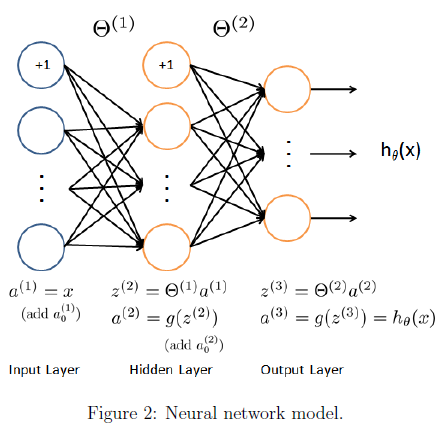

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

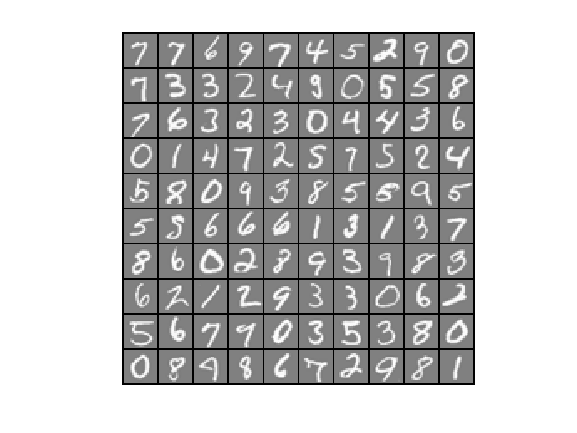

load('ex3data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));


% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.520000


The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));


Neural Network Prediction: 10 (digit 0)


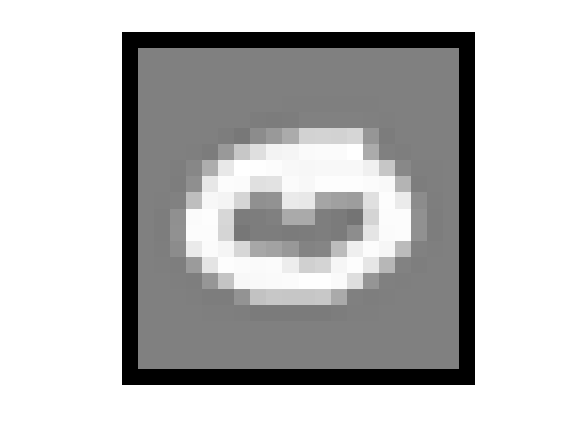

% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

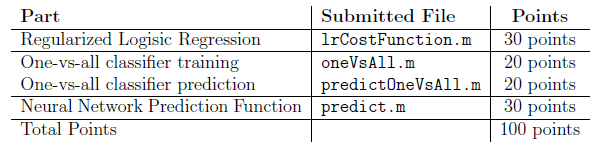

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.